# Домаћи задатак из предмета дигитална обрада сигнала

## Радила:  Драгана Нинковић 2019/0052

## Параметри: P = 4; Q = 3; R = 1; S =1; 

# Задатак 1

## Поставка задатка

clc; clear;close all;
P = 4;
n = 0:(2*P - 2);
x = ( sin(n) + 2*cos(2*n) + P/2 ).*( n >= 0 & n < floor(P/2) )...
    +( 2.^n ).*( n >= floor(P/2) & n < P );
y = ( (-1).^n + mod(n,2) ).*( n >= 0 & n < floor(P/2) )...
    +( n - P/2 ).*( n >= floor(P/2) & n < P );

## а)

## графички приказ сигнала

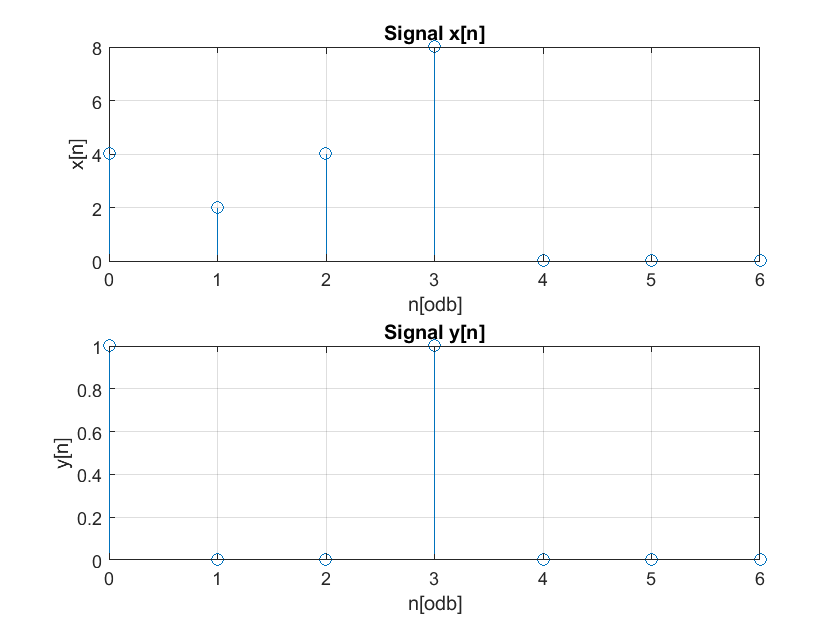

figure(1)
subplot(2,1,1)
stem(n,x);
xlabel('n[odb]');ylabel('x[n]'); 
title('Signal x[n]'); grid on;
subplot(2,1,2)
stem(n,y)
xlabel('n[odb]');ylabel('y[n]'); 
title('Signal y[n]'); grid on;

## конволуција у П+2 тачака

N = P + 2;
z = zeros(1,N);
K = 0:N-1;
for k = K
    n= k:-1:k-(N-1);% n = k - m, m = [0,N-1]
    z(k+1) = sum( x(1:N).*y( mod(n,N) + 1 ) ); % +1 zbog indeksiranja od 1
end

## графички приказ конволуције у П+2 тачака

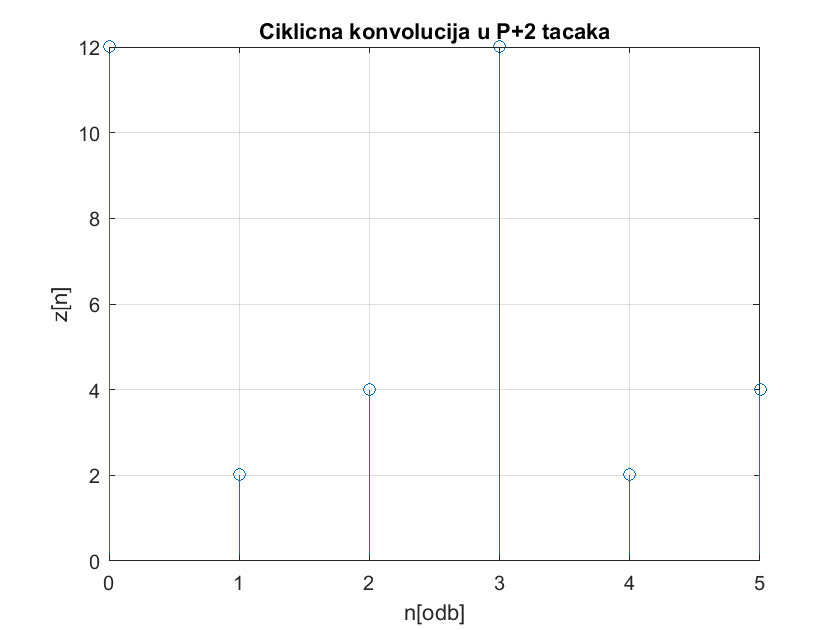

figure(2)
stem(K,z);
xlabel('n[odb]');ylabel('z[n]'); 
title('Ciklicna konvolucija u P+2 tacaka'); grid on;

## провера

disp(round(cconv(x(1:P),y(1:P),N),10) == round(z,10))

   1   1   1   1   1   1



## б)

## циклична конволуција у 2*П-1 тачака

N=2*P-1;

z = zeros(1,N);
K = 0:N-1;
for k = K
    n= k:-1:k-(N-1);% n = k - m, m = [0,N-1]
    z(k+1) = sum( x(1:N).*y( mod(n,N) + 1 ) ); % +1 zbog indeksiranja od 1
end

## линеарна конволуција

z_lin= zeros(1,N);

for k = K
    for j=0:N-1% jer se -inf do inf svede na ove granice jer je x van njih = 0
        if( (k - j + 1) > 0 )
          z_lin(k + 1) = z_lin(k + 1) + x(j + 1)*y(k - j + 1);
        end
    end 
end

## графички приказ линеарне конволуције

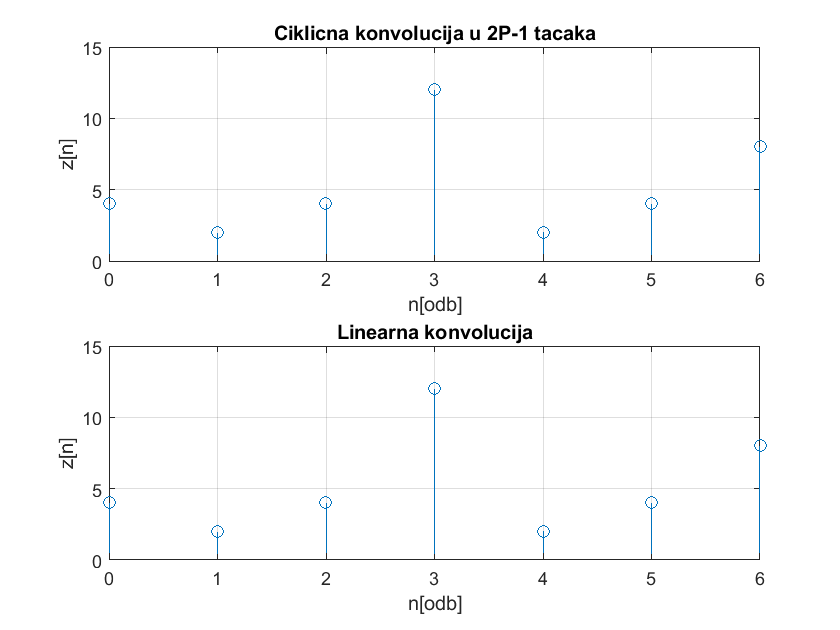

figure(3)
subplot(2,1,1)
stem(K,z);
xlabel('n[odb]');ylabel('z[n]'); 
title('Ciklicna konvolucija u 2P-1 tacaka'); grid on;
subplot(2,1,2)
stem(K, z_lin);
xlabel('n[odb]');ylabel('z[n]'); 
title('Linearna konvolucija'); grid on;

## провера

c=conv(x(1:P),y(1:P));
disp(z==z_lin)

   1   1   1   1   1   1   1



disp(z_lin==c)

   1   1   1   1   1   1   1



# Задатак 2

## унос података

clear; close all; clc;
ids=1:4;
instruments=['Truba  ';'Klavir ';'Flauta ';'Violina'];

max_len=0;%maksimalna duzina - ove duzine treba da bude zajednicka matrica
%ostali vektori ce samo biti paddovani nulama
[x1,Fs(1)] = audioread('truba_4.wav');
len(1)=length(x1);
max_len=max(max_len,len(1));
[x2, Fs(2)] = audioread('klavir_4.wav');
len(2)=length(x2);
max_len=max(max_len,len(2));
[x3, Fs(3)] = audioread('flauta_4.wav');
len(3)=length(x3);
max_len=max(max_len,len(3));
[x4, Fs(4)] = audioread('violina_4.wav');
len(4)=length(x4);
max_len=max(max_len,len(4));

%pravljenje zajednicke matrice
x=zeros(4,max_len);
x(1,1:len(1))=x1;
x(2,1:len(2))=x2;
x(3,1:len(3))=x3;
x(4,1:len(4))=x4;

## a)

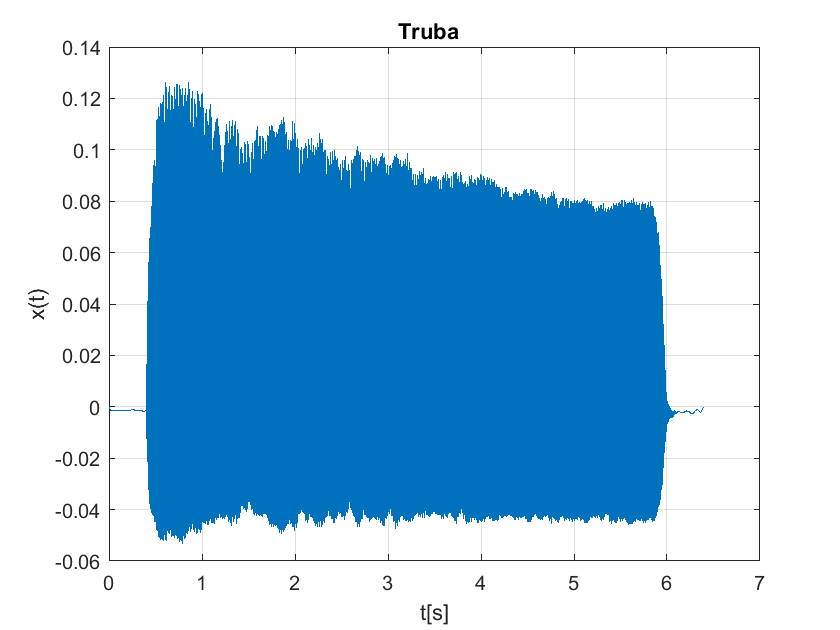

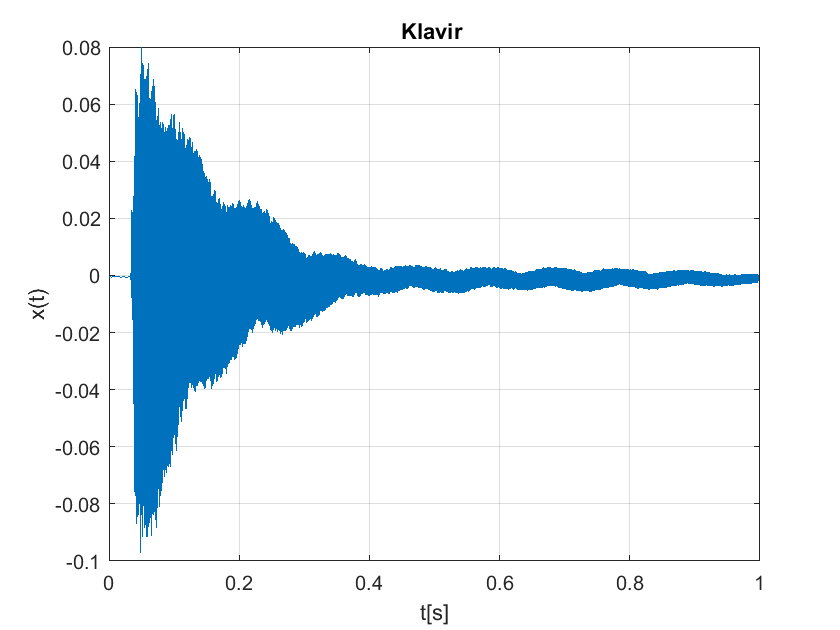

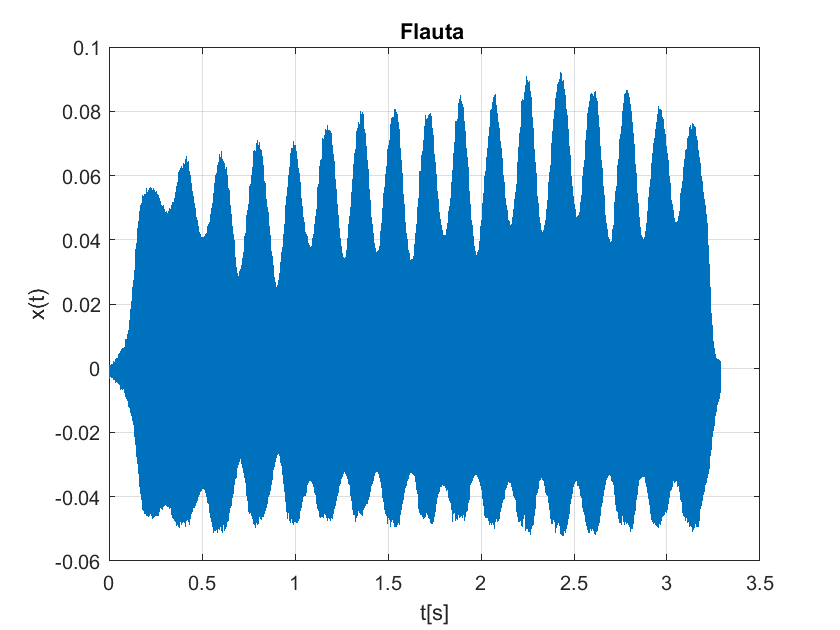

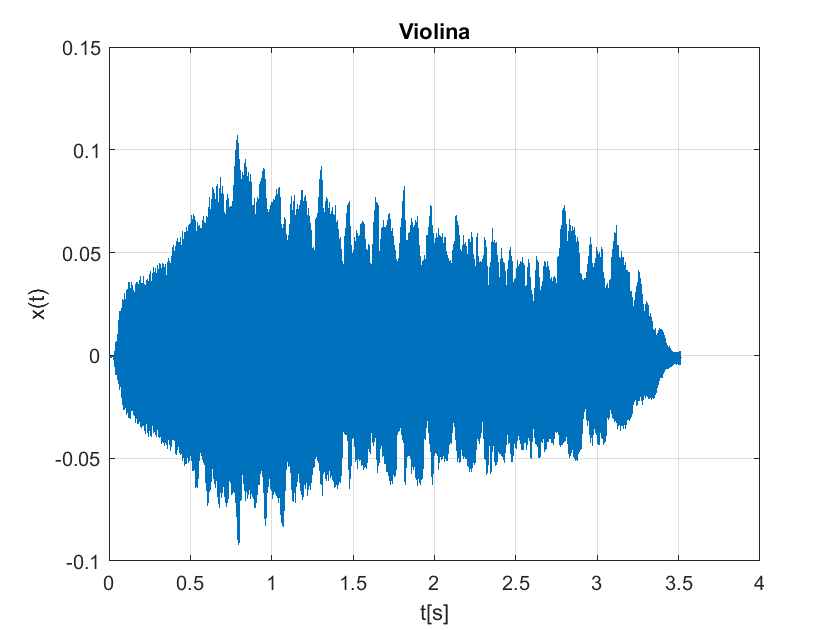

for i = ids
    t = 0:1/Fs(i):(len(i) - 1)/Fs(i);
    figure(i)
    plot(t, x(i,1:len(i)));
    xlabel('t[s]');ylabel('x(t)');
    title(instruments(i,:));grid on;
end

## б)

## амплитудска карактеристика и рачунање пикова

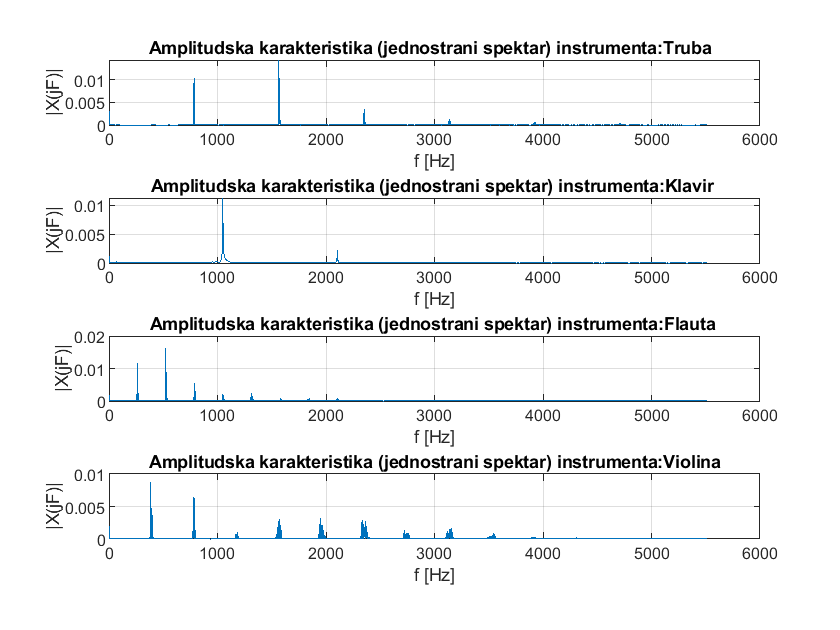

peaks = [780,1000,250,400];% prvi pik svakog signala odokativno
peaks_in_1 = [780,1550,2350,3140,3930,4710];%svi pikovi prvog signala odokativno

figure(5)
for i = ids 
    fs = Fs(i);
    N = 2^(nextpow2(len(i)));
    X = fft(x(i,1:len(i)),N)/len(i);
    Xa = abs(X(1:N/2+1));
    Xa(2:N/2+1) = 2*Xa(2:N/2+1);
    f = 0:fs/N:fs/2; 
    
    peak_id = floor(peaks(i)/(fs/N));%nalazenje odokativnog indeksa pika
    [M, id] = max(Xa(peak_id - 100:peak_id + 100));%pretraga maksimuma na +/- 100 tacaka u okolini
    peaks(i) = f(id + peak_id - 101);%nalazenje frekvencije prvog pika
    
    % nalazenje srednjeg rastojanja pikova kod prvog signala
    if(i == 1)
        for j = 1:6
            p = peaks_in_1(j);%j-ti pik
            peak_id = floor(p/(fs/N));%nalazenje tacke u njegovoj blizini
            [M, id] = max(Xa(peak_id - 100:peak_id + 100));% maksimum u +/- 100 tacaka
            peaks_in_1(j) = f(id + peak_id - 101);
        end
    end

    subplot(4,1,i) 
    plot(f, Xa); 
    xlabel('f [Hz]');ylabel('|X(jF)|');
    title(['Amplitudska karakteristika (jednostrani spektar) instrumenta:' instruments(i,:)]);grid on;  
end

## фазна карактеристика

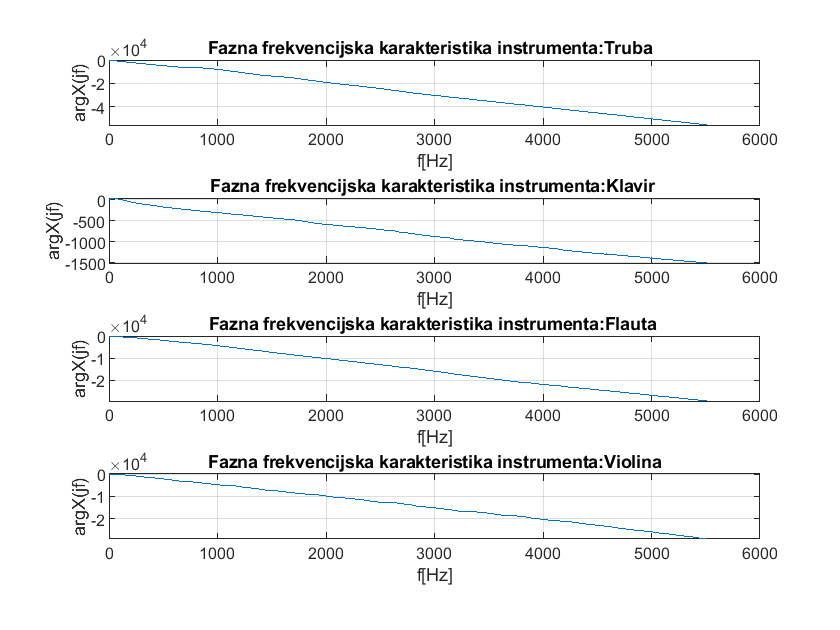

figure(6)
for i = ids
    fs = Fs(i);
    N = 2^(nextpow2(len(i)));
    f = 0:fs/N:fs/2;
    X = fft(x(i,1:len(i)),N)/len(i);
    Xphase = unwrap(angle(X(1:N/2+1)));
    subplot(4,1,i)
    plot(f,Xphase);
    title(['Fazna frekvencijska karakteristika instrumenta:' instruments(i,:)]);grid on;
    xlabel('f[Hz]');ylabel('arg{X(jf)}');
end

## ц) испис позиција првих пикова

добијене ноте су:

['Truba  ';'Klavir ';'Flauta ';'Violina'] -> 784.6-G5, 1049.1-C6, 262.4-C4, 385.9-G4

disp(round(peaks,2))

   1.0e+03 *

    0.7846    1.0491    0.2624    0.3859



## д)

sum=0;
prev=peaks_in_1(1);
for i = 1:6
    sum = sum + (peaks_in_1(j)-prev);
    prev=peaks_in_1(j);
end

## средње растојање између пикова првог сигнала је

disp(sum/5)

  784.9525



# 3. Задатак

# Дигитални филтри

## а)

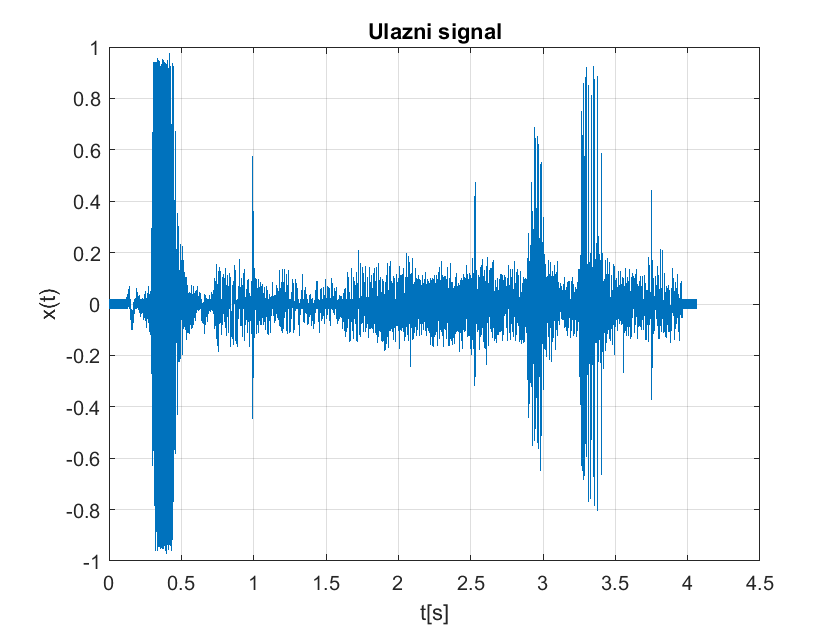

clear; close all; clc;
[x, Fs] = audioread('james_bond_zasumljen1.wav');
t = 0:1/Fs:(length(x)-1)/Fs;
figure(1)
 plot(t,x);
 xlabel('t[s]'); ylabel('x(t)');
 title('Ulazni signal'); grid on;

## б)

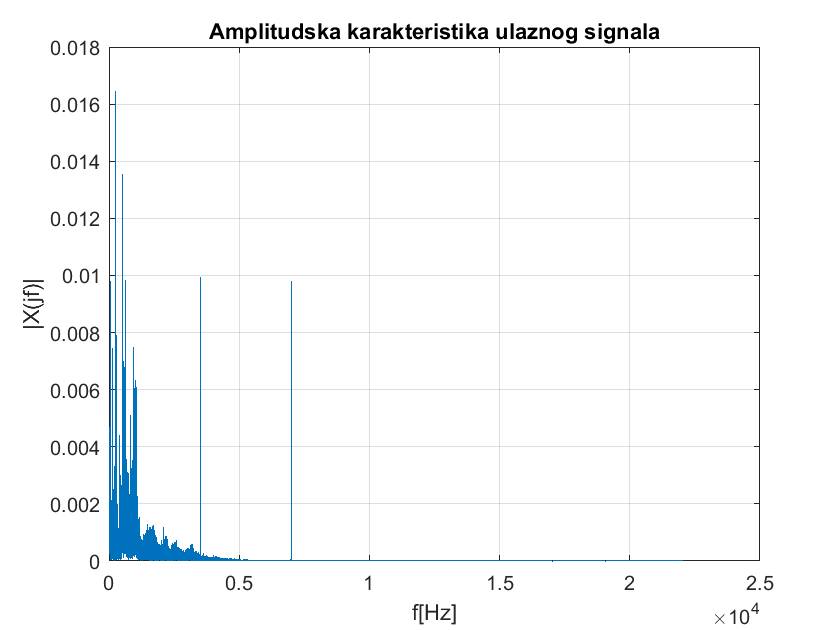

N = 2^nextpow2(length(x));
f1 = 0:Fs/N:Fs/2;
X = fft(x,N)/length(x);
X1 = abs(X(1:N/2+1));
X1(2:N/2+1) = 2*X1(2:N/2+1);

figure(2)
 plot(f1,X1);
 xlabel('f[Hz]'); ylabel('|X(jf)|');
 title('Amplitudska karakteristika ulaznog signala'); grid on;

компоненте шума су на 3500Hz i 7000 Hz

## ц)

## Одстрањивање компоненте f=3500 Hz са bandstop

Wp1 = [3400 3600]/(Fs/2);
Ws1 = [3450 3550]/(Fs/2);
Rp = 2; Rs = 40;
[n1, Wn1] = cheb2ord(Wp1, Ws1, Rp, Rs);
[b1, a1] = cheby2(n1, Rs, Ws1,'stop');
[h1, w1] = freqz(b1, a1, N/2+1);

y = filter(b1, a1, x);
Y = fft(y,N)/length(y);
Y1 = abs(Y(1:N/2+1));
Y1(2:N/2+1) = 2*Y1(2:N/2+1) ;

## Одстрањивање друге компоненте шума на f=7000 Hz bandstop

Wp2 = 6850/(Fs/2);
Ws2 = 6900/(Fs/2);

[n2, Wn2] = cheb2ord(Wp2, Ws2, Rp, Rs);
[b2, a2] = cheby2(n2, Rs, Ws2,'low');
[h2, w2] = freqz(b2, a2, N/2+1);

z = filter(b2, a2, y);
Z = fft(z,N)/length(z);
Z1 = abs(Z(1:N/2+1));
Z1(2:N/2+1) = 2*Z1(2:N/2+1) ;
audiowrite('isfiltriran1.wav', z, Fs);

## д)

## Амплитудска фазна карактеристика првог филтра

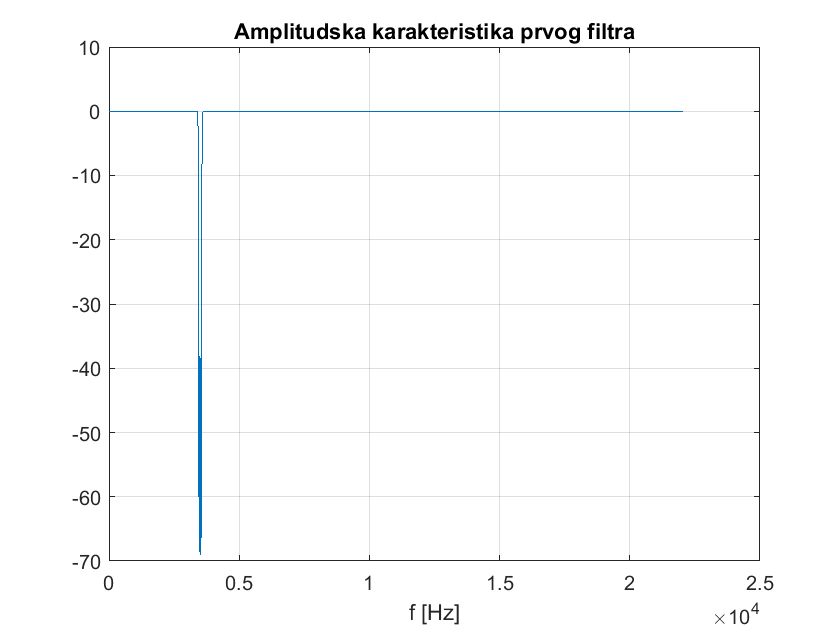

figure(3)
 plot(f1, 20*log10(abs(h1)));
 xlabel('f [Hz]');
 title('Amplitudska karakteristika prvog filtra'); grid on;

## Амплитудска фазна карактеристика другог филтра

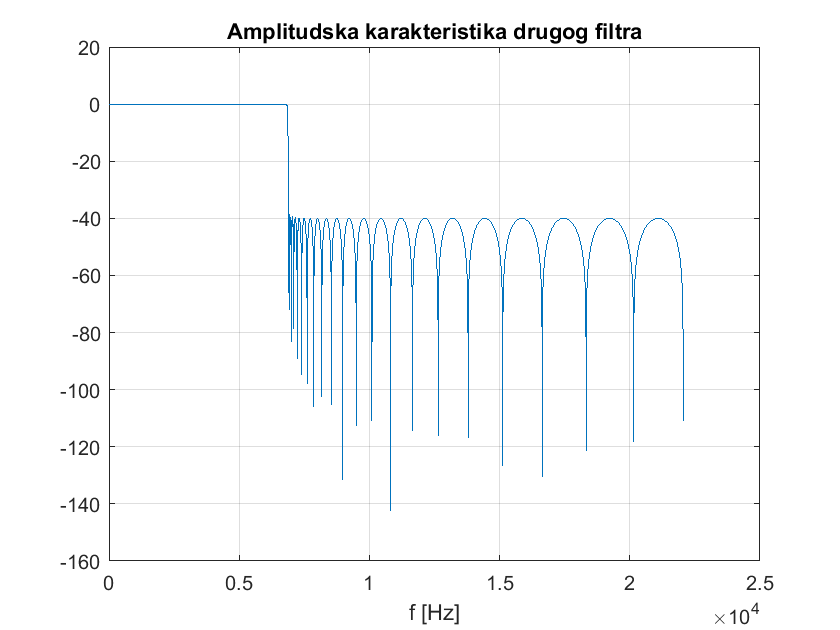

figure(4)
 plot(f1, 20*log10(abs(h2)));
 xlabel('f [Hz]');
 title('Amplitudska karakteristika drugog filtra'); grid on;

## Амплитудска карактеристика сигнала пре и након првог филтрирања

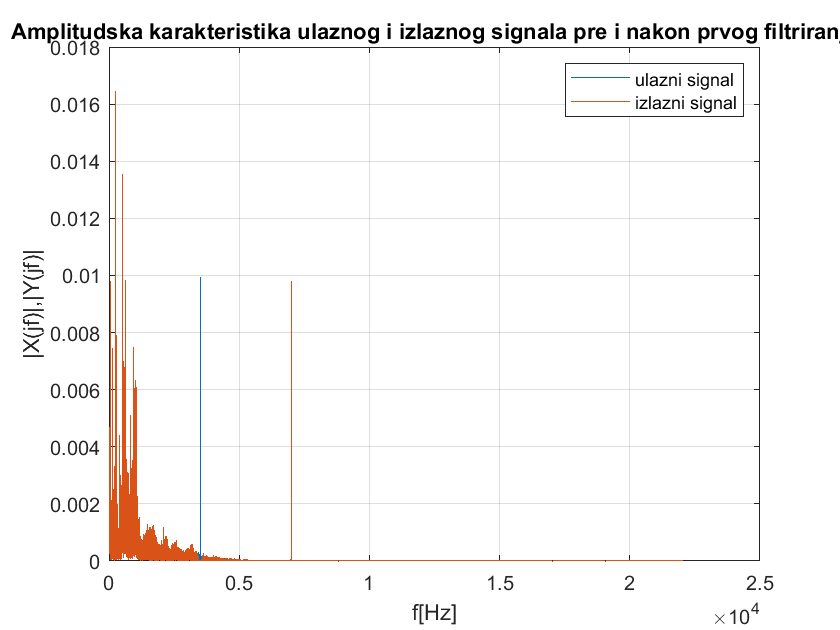

figure(5)
 plot(f1, X1); hold on
 plot(f1,Y1);
 xlabel('f[Hz]'); ylabel('|X(jf)|,|Y(jf)|');
 legend('ulazni signal','izlazni signal')
 title('Amplitudska karakteristika ulaznog i izlaznog signala pre i nakon prvog filtriranja'); grid on;

## Амплитудска карактеристика сигнала пре и након другог филтрирања

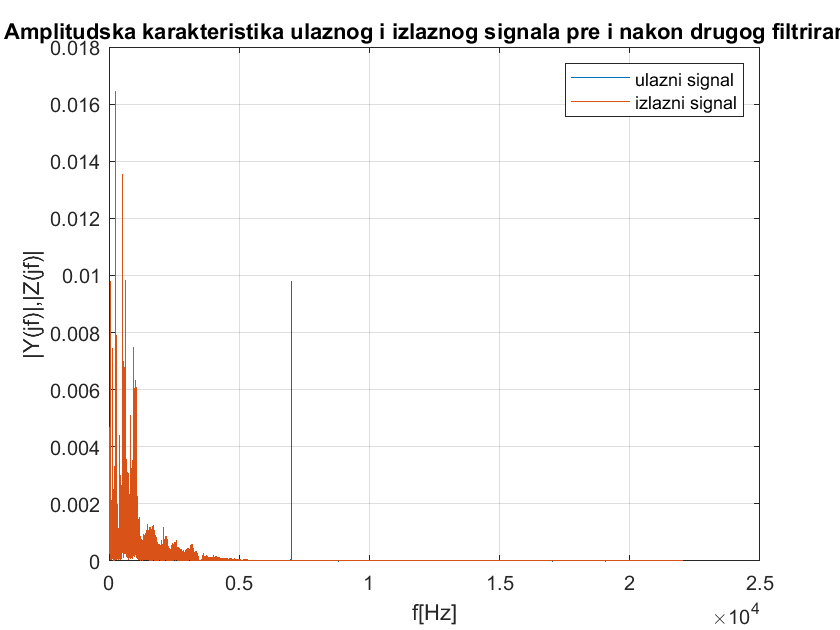

figure(6)
 plot(f1, Y1); hold on
 plot(f1,Z1);
 xlabel('f[Hz]'); ylabel('|Y(jf)|,|Z(jf)|');
 legend('ulazni signal','izlazni signal')
 title('Amplitudska karakteristika ulaznog i izlaznog signala pre i nakon drugog filtriranja'); grid on;

## Графички приказ временског облика сигнала пре и након филтрирања

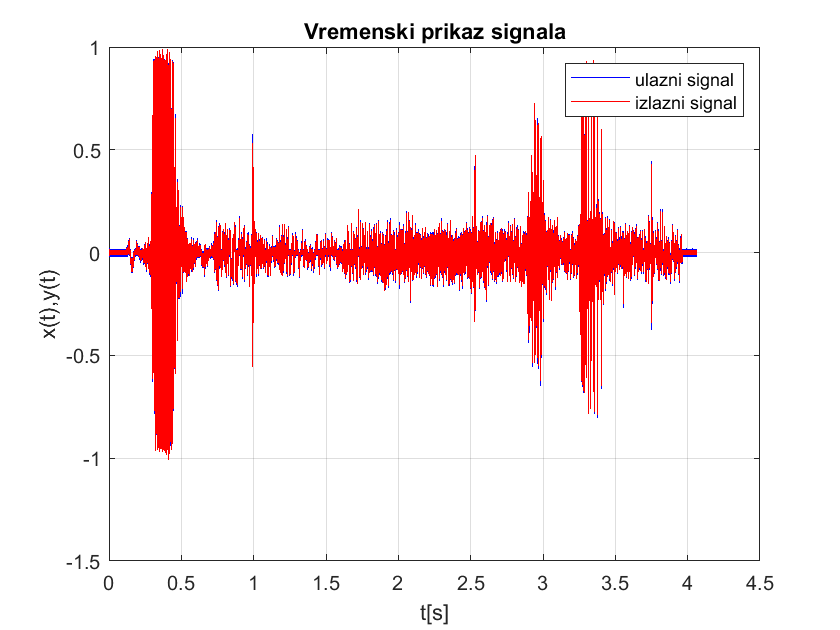

figure(7)
 plot(t,x,'b');
 hold on;
 plot(t,y,'r');
 xlabel('t[s]'); ylabel('x(t),y(t)');
 legend('ulazni signal','izlazni signal'); grid on;
 title('Vremenski prikaz signala'); 

# Аналогни филтри

clear; close all; clc;

## e)

## унос и приказ података

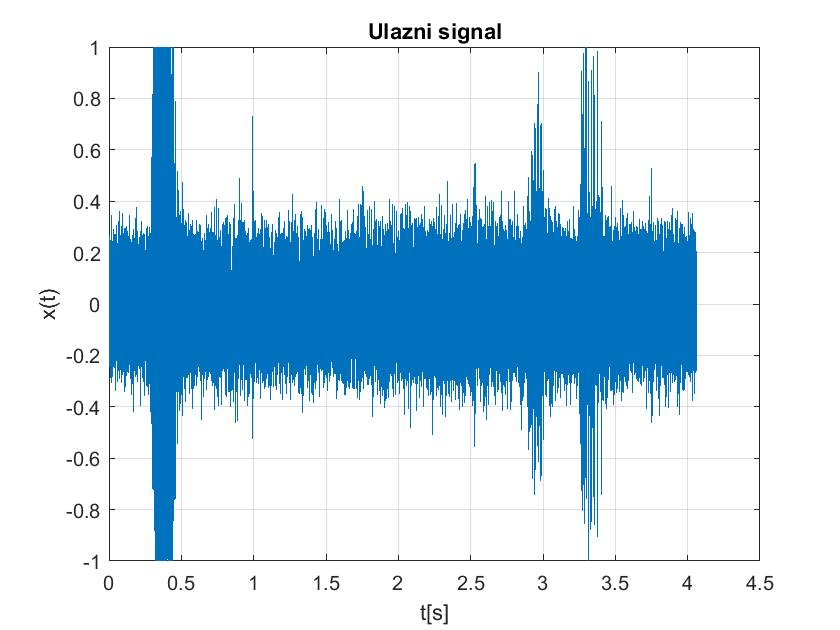

[x, Fs] = audioread('james_bond_zasumljen2.wav');
t = 0:1/Fs:(length(x)-1)/Fs;
 
figure(1)
 plot(t,x);
 xlabel('t[s]'); ylabel('x(t)');
 title('Ulazni signal'); grid on;

## приказ амплитудске карактеристике

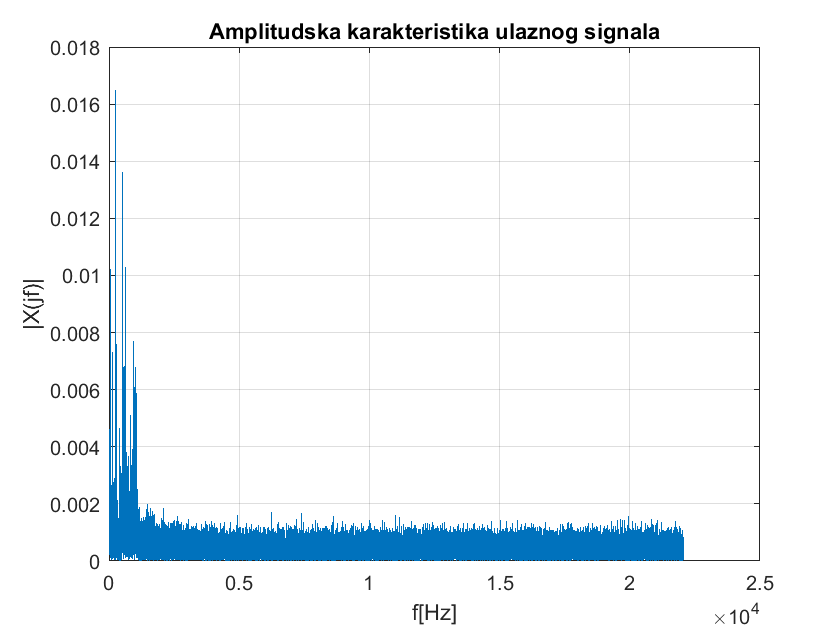

N = 2^nextpow2(length(x));
f1 = 0:Fs/N:Fs/2;
X = fft(x,N)/length(x);
X1 = abs(X(1:N/2+1));
X1(2:N/2+1) = 2*X1(2:N/2+1);
figure(2)
 plot(f1,X1);
 xlabel('f[Hz]'); ylabel('|X(jf)|');
 title('Amplitudska karakteristika ulaznog signala'); grid on;

## филтрирање

Wp = 900*2*pi;
Ws = 1500*2*pi;
Rp = 2; Rs = 50;
[n, Wn] = cheb2ord(Wp, Ws, Rp, Rs,'s');
[b, a] = cheby2(n, Rs, Ws,'s');
[h, w] = freqs(b, a, N/2+1);

## дискретизација

[bz, az] = impinvar(b, a, Fs);
[hz, fz] = freqz(bz, az, N/2+1, Fs);

## е)

## Амплитудска карактеристика дискретног и аналогног филтра

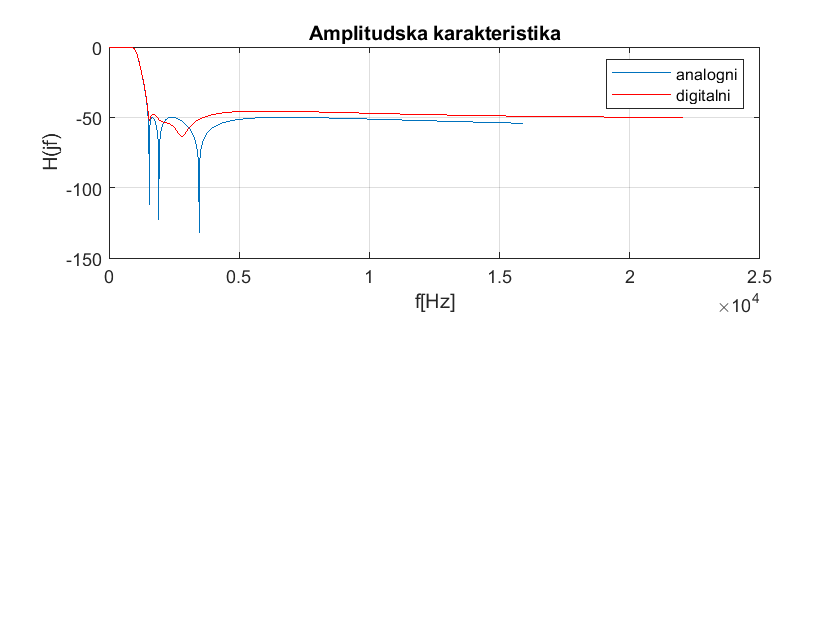

figure(3)
 subplot(2,1,1)
 plot(w/(2*pi),20*log10(abs(h)));
 hold on;
 plot(fz, 20*log10(abs(hz)),'r');
 xlabel('f[Hz]');ylabel('H(jf)');
 title('Amplitudska karakteristika');grid on;
 legend('analogni','digitalni');hold off;

## Амплитудска карактеристика сигнала пре и после филтрирања

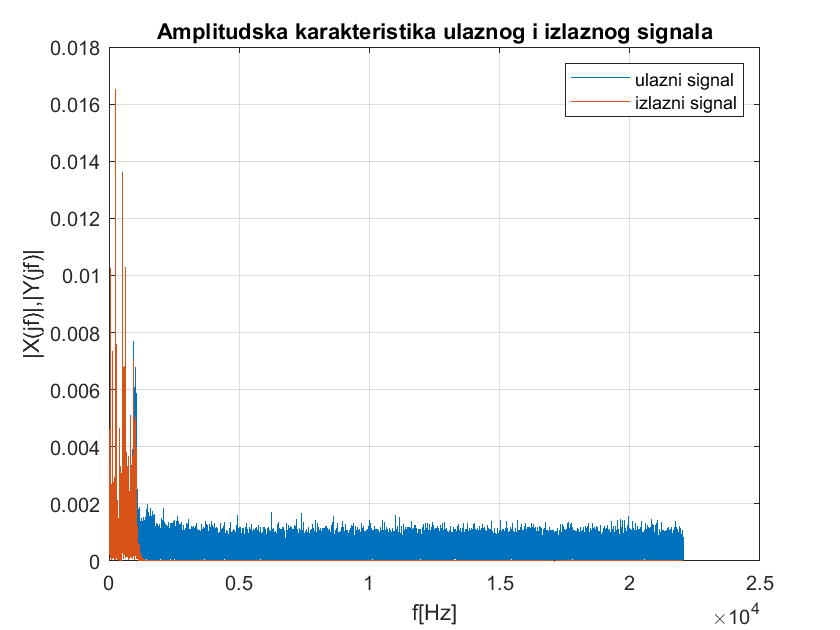

y = filter(bz, az, x);
Y = fft(y,N)/length(y);
Y1 = abs(Y(1:N/2+1));
Y1(2:N/2+1) = 2*Y1(2:N/2+1);

figure(4)
 plot(f1, X1); hold on
 plot(f1, Y1);
 xlabel('f[Hz]'); ylabel('|X(jf)|,|Y(jf)|');
 title('Amplitudska karakteristika ulaznog i izlaznog signala'); grid on;
 legend('ulazni signal','izlazni signal');hold off;

## временски облик сигнала на улазу и излазу

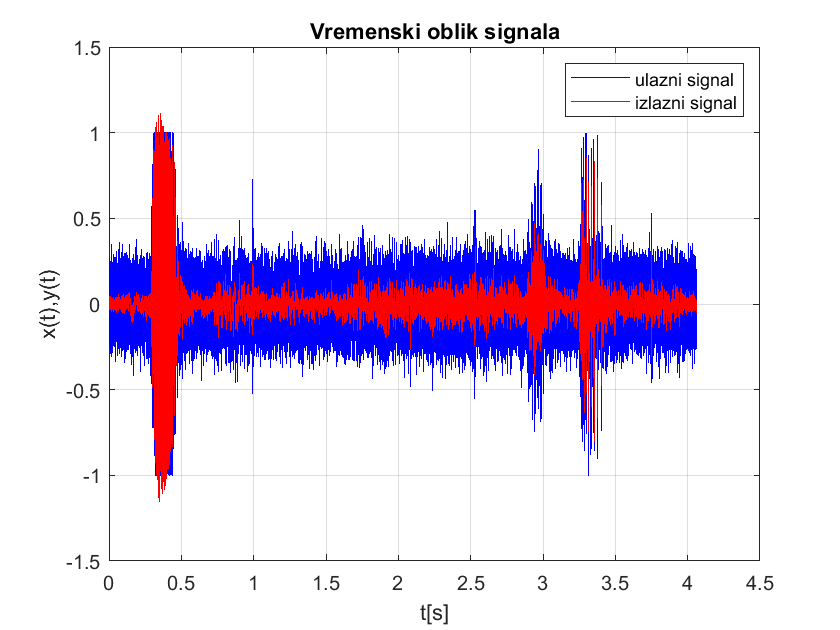

figure(5)
 plot(t,x,'b');
 hold on;
 plot(t,y,'r');
 xlabel('t[s]'); ylabel('x(t),y(t)');
 title('Vremenski oblik signala'); grid on;
 legend('ulazni signal','izlazni signal');hold off;

audiowrite('isfiltriran2.wav', y, Fs)

## Задатак 4

## унос података

clear; close all; clc;

[x,Fs] = audioread('truba_4.wav');
t = 0:1/Fs:(length(x)-1)/Fs;

N = 2^nextpow2(length(x));
f1 = 0:Fs/N:Fs/2;
X = fft(x,N)/length(x);
X1 = abs(X(1:N/2+1));
X1(2:N/2+1) = 2*X1(2:N/2+1);

## приказ амплитудске карактеристике улазног сигнала

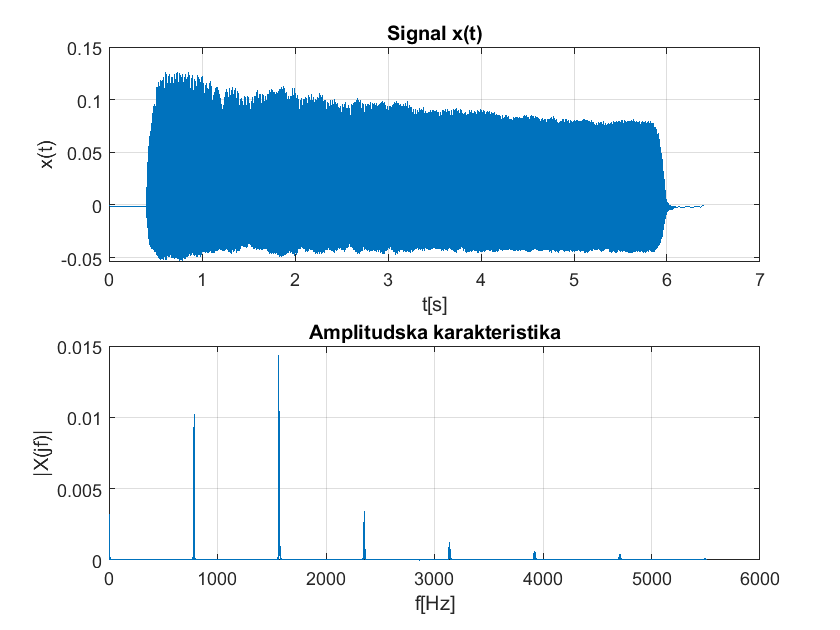

figure(1)
subplot(2,1,1)
 plot(t,x);
 xlabel('t[s]'); ylabel('x(t)');
 title('Signal x(t)'); grid on;
subplot(2,1,2)
 plot(f1,X1);
 xlabel('f[Hz]'); ylabel('|X(jf)|');
 title('Amplitudska karakteristika'); grid on;

## Креирање ФИР филтра

n = 39;
window = kaiser(n+1);
Wn = [700,800]/(Fs/2);
b = fir1(n, Wn, window);
a = 1;
[hz, fz] = freqz(b, a, N/2+1, Fs);

## Приказ прозорске функције и амплитудске карактеристике филтра

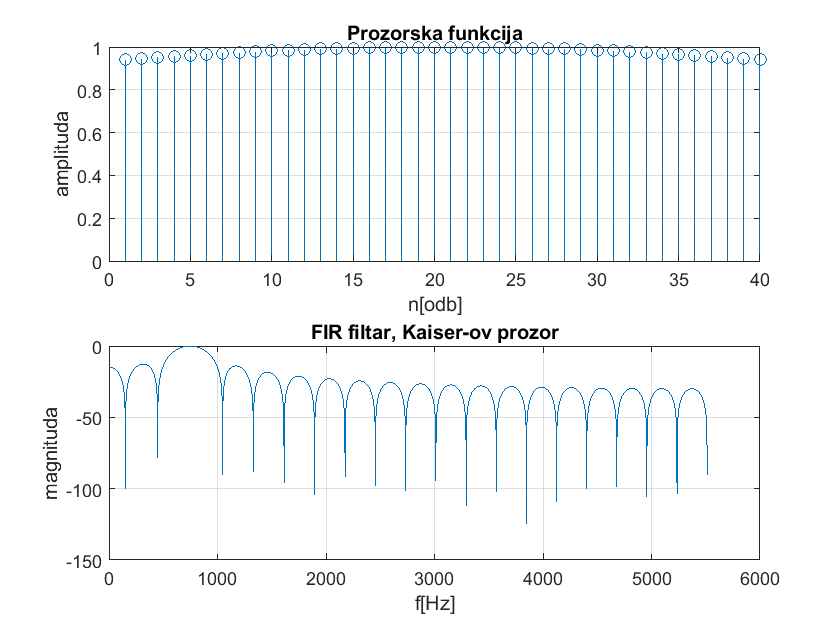

figure(2)
subplot(2,1,1)
 stem(window);
 xlabel('n[odb]');ylabel('amplituda')
 title('Prozorska funkcija'); grid on;
subplot(2,1,2)
 plot(fz, 20*log10(abs(hz)));
 xlabel('f[Hz]');ylabel('magnituda');
 title('FIR filtar, Kaiser-ov prozor'); grid on;

## филтрирање

y = filter(b, a, x);
Y = fft(y,N)/length(y);
Y1 = abs(Y(1:N/2+1));
Y1(2:N/2+1) = 2*Y1(2:N/2+1) ;

## приказ амплитудске карактеристике улазног и излазног сигнала

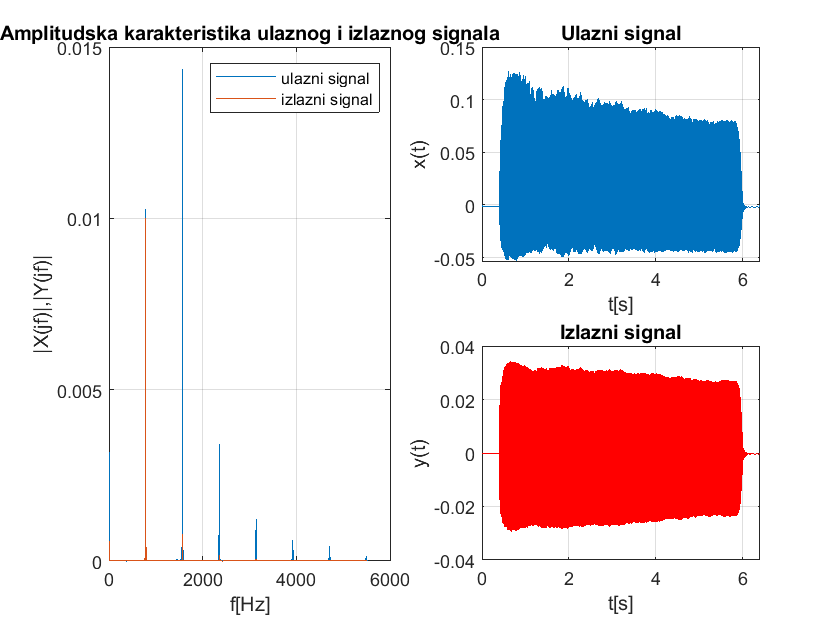

figure(3)
 subplot(2,2, [1, 3])
 plot(f1, X1); hold on
 plot(f1,Y1);
 xlabel('f[Hz]'); ylabel('|X(jf)|,|Y(jf)|');
 legend('ulazni signal','izlazni signal')
 title('Amplitudska karakteristika ulaznog i izlaznog signala'); grid on;
 subplot(2,2,2)
 plot(t,x);
 xlabel('t[s]'); ylabel('x(t)');
 title('Ulazni signal'); grid on;
 subplot(2,2,4)
 plot(t,y,'r');
 xlabel('t[s]'); ylabel('y(t)');
 title('Izlazni signal'); grid on;

 audiowrite('isfiltriran3.wav',y,Fs)

## б)

Да би дошло до ефекта замене учестаности фреквенција нашег пика 784.6 треба да буде већа од fs/2, a можемо узети и да буде < Fs да бисмо знали да је на првом косом делу јелке.

fs=Fs/9;
disp(fs/2< 784.6 & 784.6 <fs)

   1



Видимо да на овој учестаности сигурно долази до замене учестаности и да се наша фреквенција налази на првом косом делу јелке. Учестаност којом је она замењена можемо добити као:

disp(fs/2-(784.6-fs/2))

  440.4000



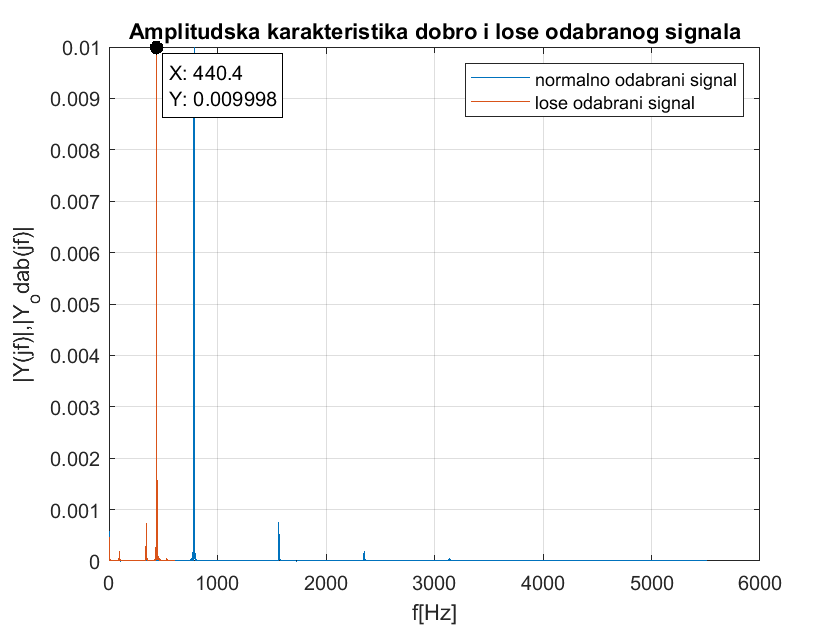

fs=Fs/9;
y_odab=y(1:9:end);
N_odab = 2^nextpow2(length(y_odab));
f1_odab = 0:fs/N_odab:fs/2;
Y_odab = fft(y_odab,N_odab)/length(y_odab);
Y1_odab = abs(Y_odab(1:N_odab/2+1));
Y1_odab(2:N_odab/2+1) = 2*Y1_odab(2:N_odab/2+1) ;
figure(4)
 plot(f1, Y1); hold on
 plot(f1_odab,Y1_odab);
 xlabel('f[Hz]'); ylabel('|Y(jf)|,|Y_odab(jf)|');
 legend('normalno odabrani signal','lose odabrani signal')
 title('Amplitudska karakteristika dobro i lose odabranog signala'); grid on;

 audiowrite('isfiltriran4.wav',y_odab,fs)